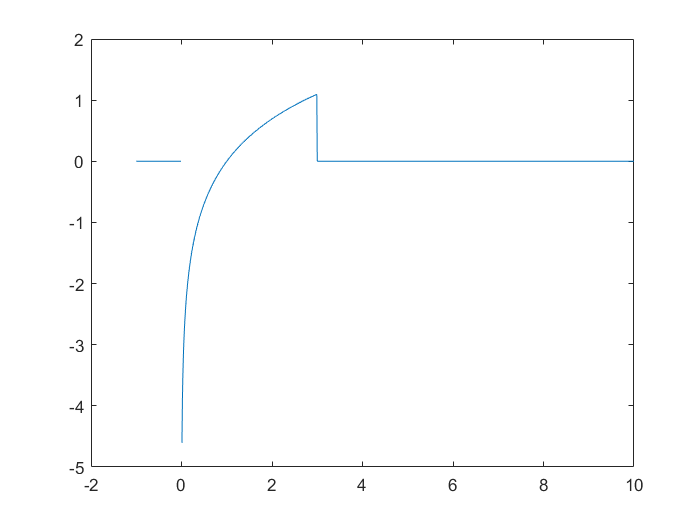

clc
clear
close all

t=-1:0.01:10;
x=log(t).*(rect(t,0,3,1));
plot(t,x);

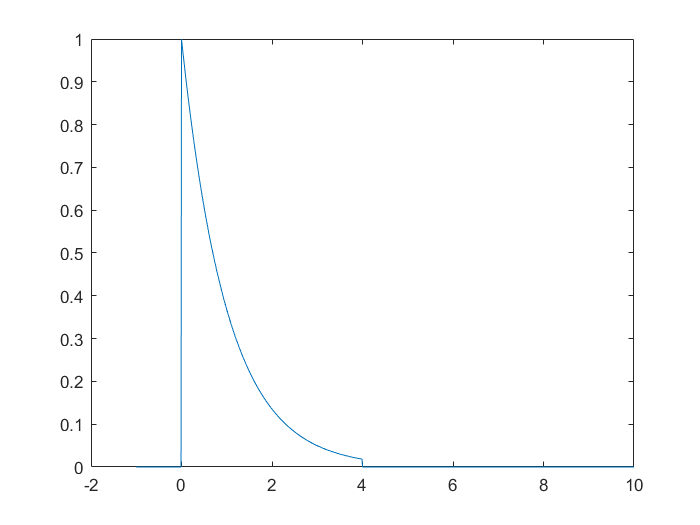

h=exp(-t).*(rect(t,0,4,1));
plot(t,h);

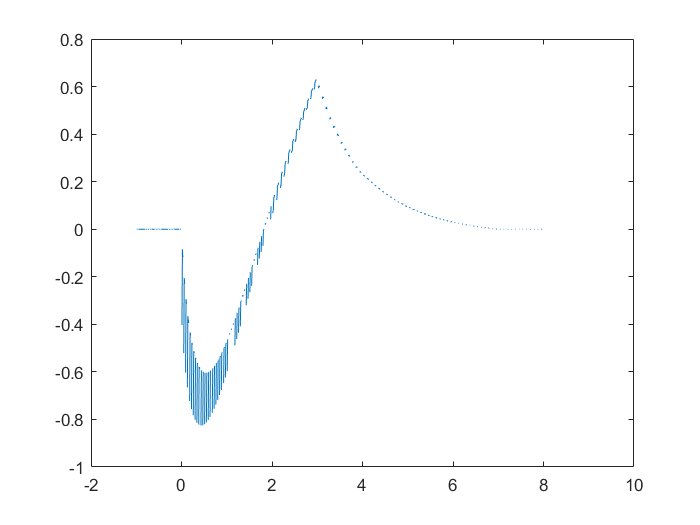

tau=-6:0.01:20;
x1=log(tau).*(rect(tau,0,3,1));
h1=exp(-tau).*(rect(tau,0,4,1));
for i=1:length(t)
    tt=t(i);
    x1_tt=log(tt-tau).*(rect(tt-tau,0,3,1));
    y_tt(i)=trapz(tau,x1_tt.*h1);
end
plot(t,y_tt);